Starting out

img = imread("year2000.jpg");
% Define binning factor
binFactor = 2; % Bin 2x2 pixels

Making  matrices to get the binned channel

redBinned = zeros(size(img, 1) / binFactor, size(img, 2) / binFactor, 'uint8');
greenBinned = zeros(size(img, 1) / binFactor, size(img, 2) / binFactor, 'uint8');
blueBinned = zeros(size(img, 1) / binFactor, size(img, 2) / binFactor, 'uint8');

Looping through rows and columns to bin pixels

for i = 1:binFactor:size(img, 1)
  for j = 1:binFactor:size(img, 2)
    % Extract sub-matrix for current bin
    subMatrix = img(i:i+binFactor-1, j:j+binFactor-1, :);
    
    % Calculate average for each channel
    redBinned(ceil(i/binFactor), ceil(j/binFactor)) = mean(mean(subMatrix(:,:,1)));
    greenBinned(ceil(i/binFactor), ceil(j/binFactor)) =mean(mean(subMatrix(:,:,2)));
    blueBinned(ceil(i/binFactor), ceil(j/binFactor)) = mean(mean(subMatrix(:,:,3)));
  end
end

Making the red, green and blue actually... red green and blue

finIm = zeros(size(redBinned),"uint8")

finIm = 400×360 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

finIm(:,:,1) = redBinned

finIm = 400×360 uint8 matrix
    36    38    37    35    34    51    64    40    37    35    36    51    60   109    66    48    29    33    34    34    35    42    35    33    29    31    31    30    34    36    35    39    35    38    36    42    46    48    49    50    47    47    46    43    42    42    43    40    40    39
    37    46    39    39    37    33    31    36    36    35    44    45    41   134   129    49    34    29    32    49    28    29    32    32    31    32    32    30    33    34    33    37    32    31    31    37    41    45    49    49    55    51    47    46    46    42    44    44    41    37
    43    37    36    35    38    34    55    41    36    40    36    57    57    22    38    48    85    55    36    58    38    34    31    29    34    34    33    31    32    32    31    33    34    29    29    29    32    35    38    40    43    49    50    44    45    39    39    37    40    37
    36    39    36    39    36    41    34    37    39    36    46  

finIm(:,:,2) = greenBinned

finIm = 400×360×2 uint8 array
finIm(:,:,1) =

    36    38    37    35    34    51    64    40    37    35    36    51    60   109    66    48    29    33    34    34    35    42    35    33    29    31    31    30    34    36    35    39    35    38    36    42    46    48    49    50    47    47    46    43    42    42    43    40    40    39    36    34    33    32    33    35    35    35    34    34    36    35    31    36    34    37    30    32    33    33    33    33    32    33    35    37    32    33    31    33    35    35    35    63    44    34    33    31    33    33    33    33    35    32    32    35    32    33    34    34    36    34    36    36    35    32    34    32    35    35    35    33    34    33    28    32    32    34    32    31    33    30    32    32    29    28    29    32    35    35    34    34    35    34    35    32    34    32    32    34    31    34    33    34    31    30    29    29    27    29    30    30    29    33    31    29    33    33    32

finIm(:,:,3) = blueBinned

finIm = 400×360×3 uint8 array
finIm(:,:,1) =

    36    38    37    35    34    51    64    40    37    35    36    51    60   109    66    48    29    33    34    34    35    42    35    33    29    31    31    30    34    36    35    39    35    38    36    42    46    48    49    50    47    47    46    43    42    42    43    40    40    39    36    34    33    32    33    35    35    35    34    34    36    35    31    36    34    37    30    32    33    33    33    33    32    33    35    37    32    33    31    33    35    35    35    63    44    34    33    31    33    33    33    33    35    32    32    35    32    33    34    34    36    34    36    36    35    32    34    32    35    35    35    33    34    33    28    32    32    34    32    31    33    30    32    32    29    28    29    32    35    35    34    34    35    34    35    32    34    32    32    34    31    34    33    34    31    30    29    29    27    29    30    30    29    33    31    29    33    33    32

Displaying images

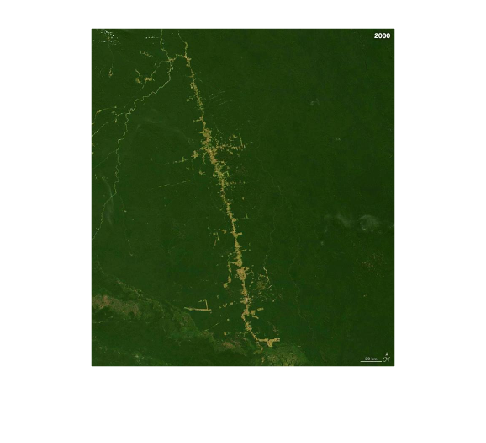

imshow(finIm)

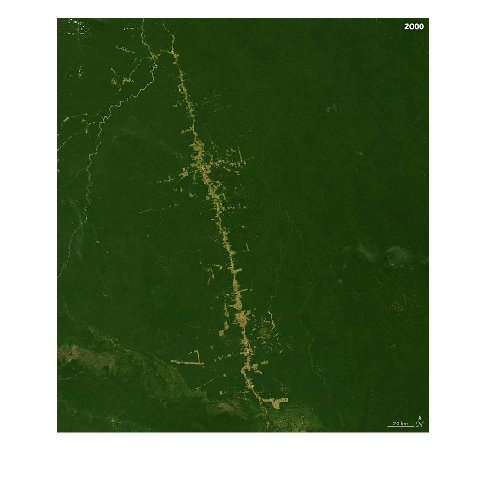

imshow(img)

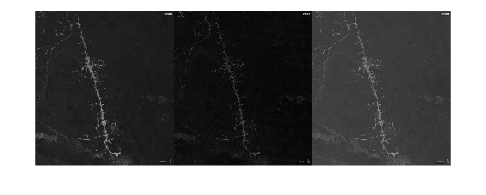

montage({red, blue, green}, 'Size', [1 3])